## **Inductor  design for  DPT circuit of Powerized/Hemizero Project**

####  by Enes Ayaz 2023-09 

A DPT is a tool which enables a power switch to be turned on and off at different current levels as shown in figure below. By adjusting the switching times T1, T2 and T3 the turn on and turn off waveforms of the Device Under Test (DUT) can be controlled and measured over the full range of operating conditions.

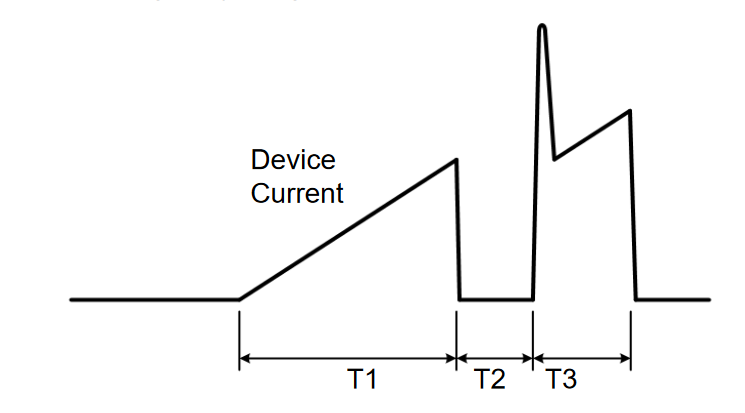

The switching times T1, T2, T3 and hence, currents can be adjusted using a programmable pulse generator. A load inductor limits the rate of di/dt. The key considerations for the selection of this inductor include:

- It should not saturate at the peak test currents.

- It should limit the di/dt so that the switching times (T1, T2 and T3) are not less than 10 μs, to ensure the devices have fully turned on or off.

- The di/dt should not be so low that the switching times are longer than 200 μS so as not to cause the DC bus voltage to dip by more than ≈5 percent, and so change the switching performance. In addition, if the current pulse is long, then the chip temperature can increase by more than a few °C, again affecting the switching performance.

- The inductor should be mounted well away from the test setup to prevent EMI interference or magnetic field coupling into any gate drive circuits or instrumentation.

For more information check them: 

- [1] Double Pulse Testing: The How, What and Why (By David Levett, Ziqing Zheng and Tim Frank, Infineon Technologies)

- [2] A Low Inductance, High Power Density 3L-TNPC Power Module for More-Electric Aircraft Applications

- [3] Design and Evaluation of a 1200-V/200-A SiC Three-Level NPC Power Module 

In [3], 1200V 200A  module for  3L NPC is used and the load inductance for DPT is selected as 318 uH air core inductor.

L= 318e-6; % uH
I=200;    % A
Vdc=1200;   %V
T = (L*I/1200); % in s

disp (strcat('Required time duration is',{' '},string(T*1e6),{' '},'us'))

Required time duration is 53 us


Therefore, we can select the time duration around 50 us. 

%% DC link voltage and test current
Vdc= 1200; %V
IL= 400;   %A

% Select time duration between 10u and 200us
T= 50e-6; % us

% Calculate the required inductance value 
L= (Vdc*T/IL); % in H

disp (strcat('Required indcutance is',{' '},string(L*1e6),{' '},'uH'))

Required indcutance is 150 uH



% Calculate the total storage energy
E= (1/2)*L*IL*IL; % in Joule

disp (strcat('Stored energy is',{' '},string(E),{' '},'J'))

Stored energy is 12 J


Now, we design the physical size of the inductor, providing the desired inductance value. We plan to use an air core cyclindirical inductor like the inductor in the figure below. 

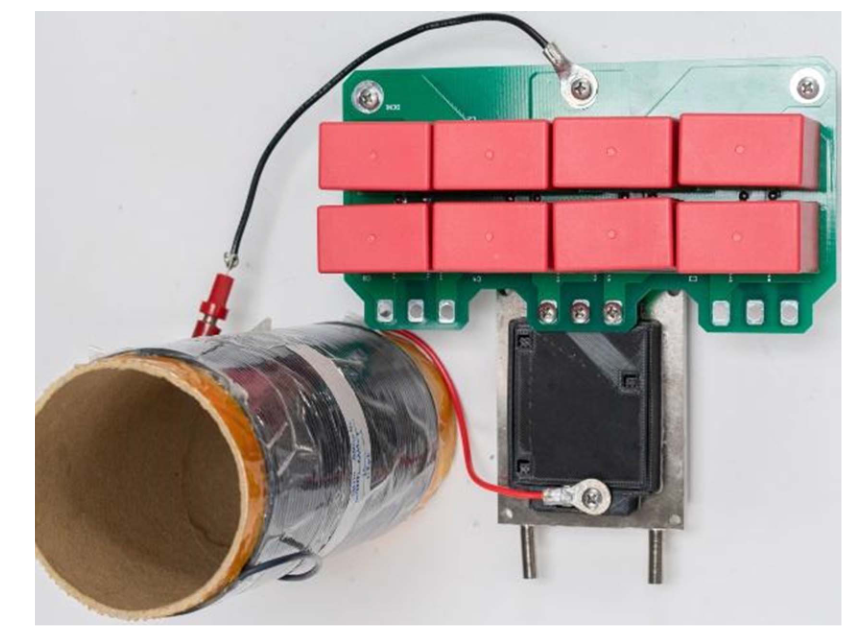

This inductor is to be a single-layer multi-turn coils. Each turn is wound around a cylindrical coil former and there is a spacing distance for insulation between the turns.

 The self-inductance of a single-turn circular coil with an air core can be calculated using the following formula:$L=\frac{\mu_{0\;} A}{r\;}{=\;\mu }_{0\;} \;\pi \;r$

- A is the cross-sectional area of one of the coils in square meters.

- *L* is the self-inductance in henries (H).

- $\mu_{0\;}$ is the permeability of free space, approximately equal to  4*π*×10−7 H/m.

- r is the radius of the circular coil in meters (m).

To calculate the mutual inductance (*M*) between two single-turn circular coils with an air core, you can use the following formula: $M=\frac{\;\mu_{0\;} \pi \;r^2 }{2\;\pi \;d}=\frac{\;\mu_{0\;} r^2 }{2\;d}$

- *d* is the distance between the centers of the two coils in meters (m).

% Constants
mu_0 = 4 * pi * 1e-7; % Permeability of free space (H/m)

%  Provide physical parameters of inductor 
r = 10e-2 ; % radius of the circular coil in meters (m)
d = 5e-3 ; % ditance between the centers of the two coils in meters (m).

N = 1; % Start with one turn

% Initialize a tolerance value for convergence
% tolerance = 10e-6;

% Select the desired inductance
target_inductance=150e-6;

while true
    % Calculate the self-inductance for each turn
    self_inductance = N*mu_0*pi*r;
    mutual_inductance= 0;
    for i=2:N 
    for j=1:(i-1) 
    mutual_inductance= mutual_inductance + (mu_0*r*r)/(2*j*d);
    end
    end
    
    inductance=self_inductance+mutual_inductance;

    % Check if the inductance is close enough to the target
    if inductance >target_inductance
        break; % If close enough, exit the loop
    else
        % Increment the number of turns and continue iterating
        N = N + 1;
    end

end

disp (strcat('Achieved indcutance is',{' '},string(inductance*1e6),{' '},'uH'))

Achieved indcutance is 152.2201 uH


disp (strcat('Required turn ratio is',{' '},string(N)))

Required turn ratio is 35




disp (strcat(['If it was wound as concentrated coils, we would achieve' ...
    ''],{' '},string(self_inductance*N*1e6),{' '},'uH'))

If it was wound as concentrated coils, we would achieve 483.6106 uH



matlab.internal.liveeditor.openAndConvert ('inductor_design.mlx', 'inductor_design.pdf');